*Copyright 2025 The MathWorks, Inc.*

# **EXERCISE 2 : 5G** **Intercell Interference Modeling**

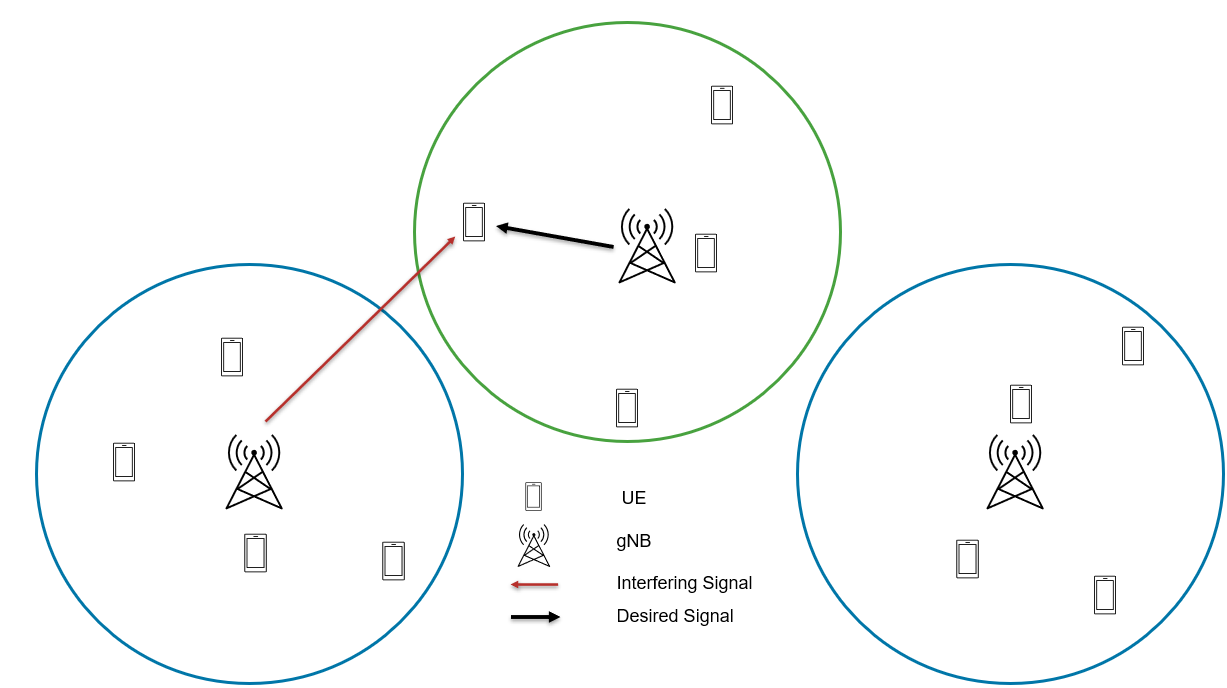

This excercise shows how to simulate a multicell interference scenario and measure the impact on network performance due to downlink (DL) intercell interference caused by nearby cells. The goals are:

- Model a multi-cell network scenario

- Analyze the impact on user throughput, particularly for users near the cell edge

- Visualize how channel conditions change as a result of inter-cell interference                            

#### Initialize Variables and Wireless Network Simulator

wirelessnetworkSupportPackageCheck
all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows 
p = addpath('.\Shared\Helpers\','.\Shared\Utilities\'); % Add path to helpers and utilities 
rng("default")                             % Reset the random number generator
numFrameSimulation = 20; % Simulation time in terms of number of 10 ms frames
networkSimulator = wirelessNetworkSimulator.init;

#### Specify the positions of 3 gNBs and the gNB of interest for visualizing metrics

numCells = 3;
gNBPositions = [1700 600 30; 3000 600 30; 2500 2000 30];
gNBOfInterestIdx = 3; % Specify an integer value in the range [1, number of gNBs]
carrierFrequency = [2.5e9, 2.5e9, 3.5e9];
gNBNames = "gNB-" + (1:size(gNBPositions,1));
for cellIdx = 1:numCells
    gNBs(cellIdx)    = nrGNB(CarrierFrequency=carrierFrequency(cellIdx),Name=gNBNames(cellIdx),Position=gNBPositions(cellIdx,:),ChannelBandwidth=10e6,SubcarrierSpacing=30e3,TransmitPower=32,ReceiveGain=11,SRSPeriodicityUE=5);
    configureScheduler(gNBs(cellIdx),ResourceAllocationType=1)
end

#### Generate the positions of UE nodes in each cell.

UEs = cell(numCells,1);
numUEsPerCell = 4;
cellRadius = 500; % Radius of each cell (in meters)
uePositions = generateUEPositions(cellRadius,gNBPositions,numUEsPerCell);

#### Create Cell #1 

cellIdx = 1;
ueNames = ["UE-1";"UE-2";"UE-3";"UE-4"];
uePos = uePositions{cellIdx};
UEs{cellIdx} = nrUE(Name=ueNames,ReceiveGain=11,Position=uePos);
connectUE(gNBs(cellIdx),UEs{cellIdx},CSIReportPeriodicity=10,FullBufferTraffic="DL")

# Task #1 Create Cell #2 

cellIdx = 2;
ueNames = ["UE-1";"UE-2";"UE-3";"UE-4"];
uePos = uePositions{cellIdx};
UEs{cellIdx} = nrUE(Name=ueNames,ReceiveGain=11,Position=uePos);
% Use connectUE() function to connect gNB of cell-2 to corresponding UEs
% Hint:Click the following link, and see the "Syntax" section.

[Help on connecting UEs to gNB  ](https://www.mathworks.com/help/5g/ref/nrgnb.connectue.html)

% Note : use the following values to start with
%    gNBs(cellIdx) 
%    UEs{cellIdx}  
%    CSIReportPeriodicity=5
%    FullBufferTraffic="DL"
%    BSRPeriodicity=5
%    CellIdx is 2 and gNBs(cellIdx) is gNb in cell 2
%    UEs{cellIdx}  is all the UEs present in cell-2 
%    
%    A note of full buffer traffic  
%    
% Full buffer traffic represents a traffic model where the transmit buffer 
% is always full, meaning the node continuously has data to send at all times. 
% This model is particularly useful for network simulations focused on 
% evaluating the performance of the MAC and PHY layers, as it eliminates 
% the variability introduced by higher-layer traffic patterns.
    

connectUE(gNBs(cellIdx), ...
    UEs{cellIdx}, ...
    CSIReportPeriodicity=5, ...
    FullBufferTraffic="DL", ...
    BSRPeriodicity=5);

#### Create Cell #3 

cellIdx = 3;
ueNames = ["UE-1";"UE-2";"UE-3";"UE-4"];
uePos = uePositions{cellIdx};
UEs{cellIdx} = nrUE(Name=ueNames,ReceiveGain=11,Position=uePos);
connectUE(gNBs(cellIdx),UEs{cellIdx},CSIReportPeriodicity=10,FullBufferTraffic="DL")

#### Add gNBs and UEs to the network simulator.

addNodes(networkSimulator,gNBs);
for cellIdx = 1:numCells
    addNodes(networkSimulator,UEs{cellIdx})
end

#### Use 3GPP TR 38.901 channel model for all links. You can also use free space path loss (FSPL) model.

channelModel = "3GPP TR 38.901";

if strcmp(channelModel,"3GPP TR 38.901")
    % Define scenario boundaries
    pos = [reshape([gNBs.Position],3,[])];
    minX = min(pos(1,:));          % x-coordinate of the left edge of the scenario in meters
    minY = min(pos(2,:));          % y-coordinate of the bottom edge of the scenario in meters
    width = max(pos(1,:)) - minX;  % Width (right edge of the 2D scenario) in meters, given as maxX - minX
    height = max(pos(2,:)) - minY; % Height (top edge of the 2D scenario) in meters, given as maxY - minY
  
    % Create the channel model
    channel = h38901Channel(Scenario="UMa",ScenarioExtents=[minX minY width height]);
    % Add the channel model to the simulator
    addChannelModel(networkSimulator,@channel.channelFunction);
    connectNodes(channel,networkSimulator,InterfererHasSmallScale=true);
end

#### Get the cell ID for the gNB of interest. The visualizations and metrics displayed are for this cell

cellToAnalyze = gNBs(gNBOfInterestIdx).ID;
simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNBs(cellToAnalyze),UEs{cellToAnalyze},LinkDirection=0);

#### Set metrics visualization

metricsVisualizer = helperNRMetricsVisualizer(gNBs(cellToAnalyze),UEs{cellToAnalyze},CellOfInterest=cellToAnalyze,RefreshRate=100,PlotSchedulerMetrics=true,PlotPhyMetrics=false,LinkDirection=0);
gridVisualizer = helperNRGridVisualizer(numFrameSimulation,gNBs(cellToAnalyze),UEs{cellToAnalyze}, ResourceGridVisualization=false,SchedulingLogger= simSchedulingLogger, CQIGridVisualization=true,CellOfInterest=cellToAnalyze);

#### Add a mobility model to the UE node of interest in the cell of interest.

enableMobility = true;
if enableMobility
    ueSpeedRange = [70 140]; % In meters per second (250 Kmph to 500 Kmph)
    ueWithMobility = UEs{cellToAnalyze}(2); % Get UE-2 in the cell of interest
    % Add random waypoint mobility to the selected UE
    addMobility(ueWithMobility, ...
        SpeedRange=ueSpeedRange, ...
        BoundaryShape="circle", ...
        Bounds=[gNBs(cellToAnalyze).Position(1:2) cellRadius])
end

#### Display the network topology

networkVisualizer = helperNetworkVisualizer(SampleRate=1000); % Sample rate indicates the visualization refresh rate in Hertz
% Show the cell boundary of each gNB
showBoundaries(networkVisualizer,gNBPositions,cellRadius,cellToAnalyze)

#### Run the simulation for the specified `numFrameSimulation` frames.

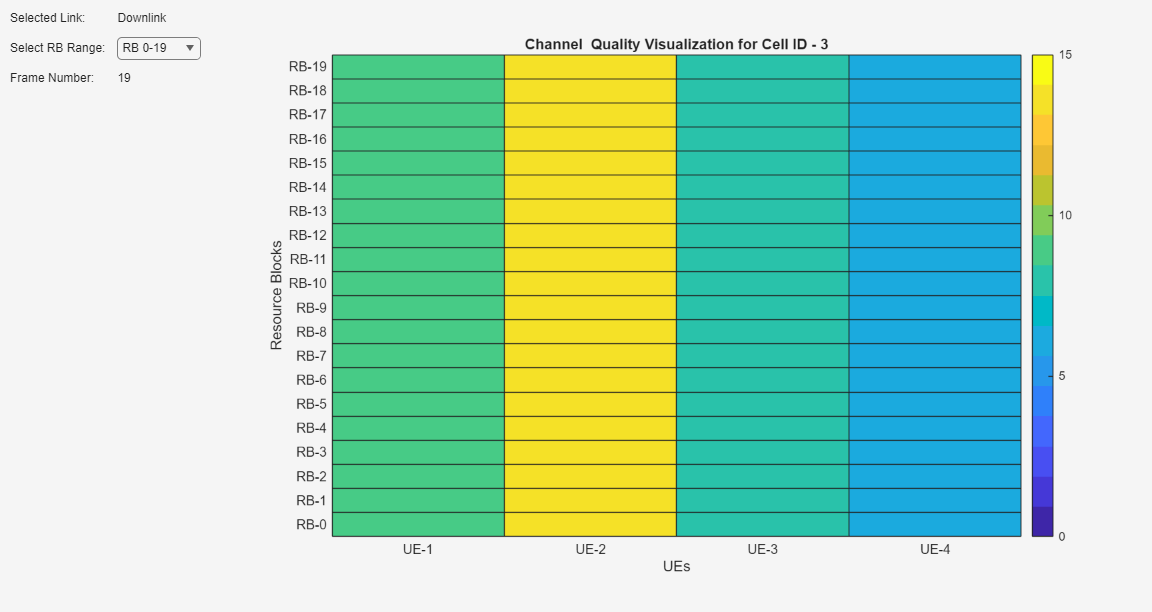

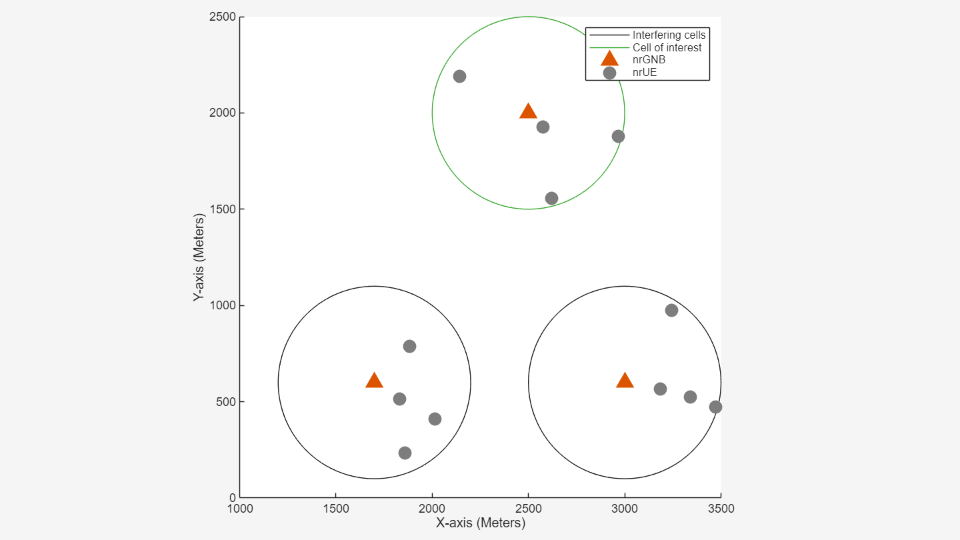

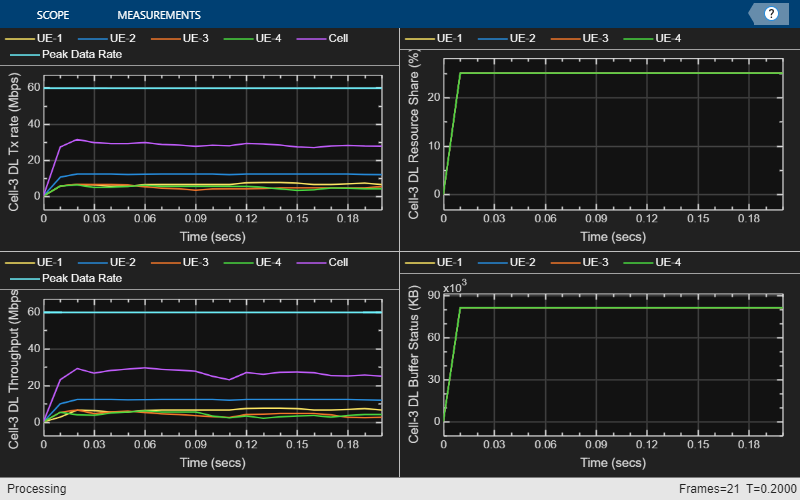

% Calculate the simulation duration (in seconds)
simulationTime = numFrameSimulation*1e-2;
% Run the simulation
run(networkSimulator,simulationTime);

displayPerformanceIndicators(metricsVisualizer)

Peak DL throughput: 59.72 Mbps. Achieved cell DL throughput: 26.63 Mbps
Achieved DL throughput for each UE: [6.39         12.1         4.15         3.99]
Peak DL spectral efficiency: 5.97 bits/s/Hz. Achieved DL spectral efficiency for cell: 2.66 bits/s/Hz
Block error rate for each UE in the DL direction: [0.02           0       0.138       0.178]



path(p);

#### Suggested Experiment:

**#1 **

Switch the channel model from the 3GPP TR 38.901 specification to a Free Space Path Loss (FSPL) model and analyze the impact on key performance indicators such as throughput and spectral efficiency.

Observe and explain why the performance of the cell of interest degrades under the FSPL model.

**#2 **

Modify the carrier frequency of Cell-3 to 3.5 GHz and evaluate the resulting effects on key performance indicators, including throughput, spectral efficiency, and channel quality indicator (CQI).

**#3**

Comment out `rng("default")` in the code to prevent resetting the random number generator. This will result in randomized UE positions across all cells in each simulation run.

Pay particular attention to UEs in the cell of interest—especially those located near cell edges or close to neighboring cells—as they are more affected by inter-cell interference. This impact is reflected in the performance metrics such as throughput.

*Copyright 2020-2024 The MathWorks, Inc.*